## Plant definition


$$P_{\alpha } \left(s\right)=\frac{-0\ldotp 5125\left(s^2 +45\ldotp 915\right)}{s^2 \left(s^2 -36\ldotp 225\right)}$$


## Calculate the Feedback Controller

#### 我的版本

W = 300;

% unshaped plant P(s)
plant_num   = -0.5125 * [1 0 45.915];
plant_denum = [1 0 -36.225 0 0];
P = tf(plant_num, plant_denum);

% compute C2_hat using shaped plant data
C2_hat = TwoDOFFeedbackTuningFunction(W*plant_num, plant_denum);

谱分解无明显误差



% absorb W
C2 = W * C2_hat;

% loop (feedback only)
S = feedback(1, minreal(P*C2));

% IMPORTANT: do NOT overwrite C2 afterwards
C1 = TwoDOFtuningFunction(plant_num, plant_denum, C2,[1,1,1,1]);

G = minreal((P*C1)/(1 + P*C2));

% Stability checks
isstable(S), pole(S);

ans = logical
   1


isstable(G), pole(G);

ans = logical
   1


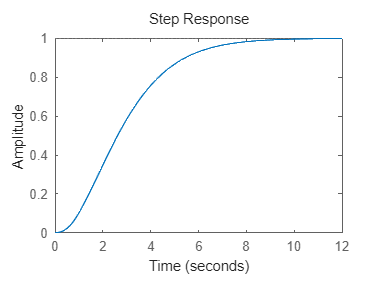

%step(G);
step(G);